-----------------------YHKCOPYRIGHT--------------------------

HOMEWORK_2 May 23rd ---------- B23042424 袁浩宽

-------------------------------------------------------------------------

P46  

5 .（1）

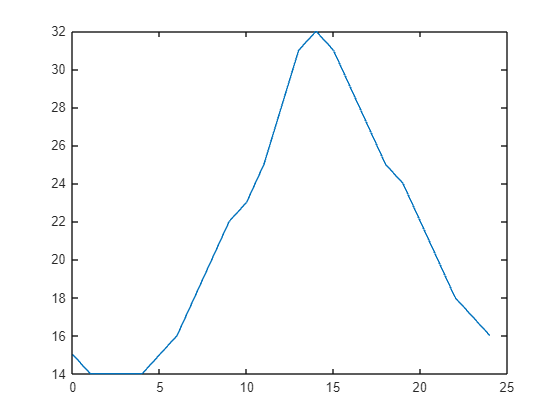

t=[0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24];
T=[15 14 14 14 14 15 16 18 20 22 23 25 28 31 32 31 29 27 25 24 22 20 18 17 16];
plot(t,T);

6（1）

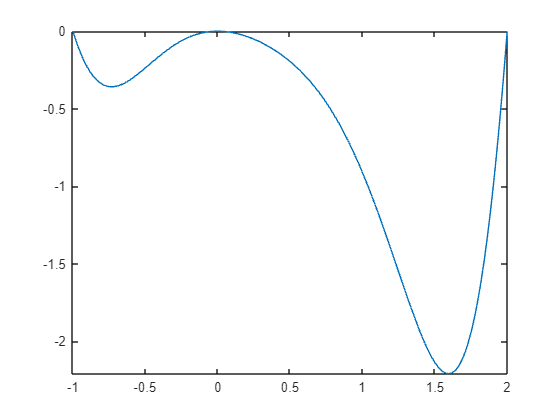

fplot(@(x)x.^2.*sin(x.^2-x-2),[-1,2]);

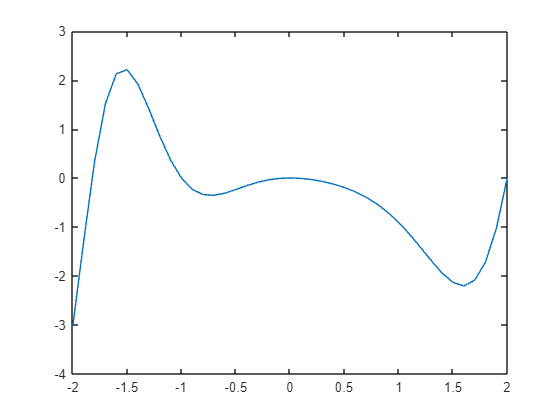

x=-2:0.1:2;
y=x.^2.*sin(x.^2-x-2);
plot(x,y);

（2）

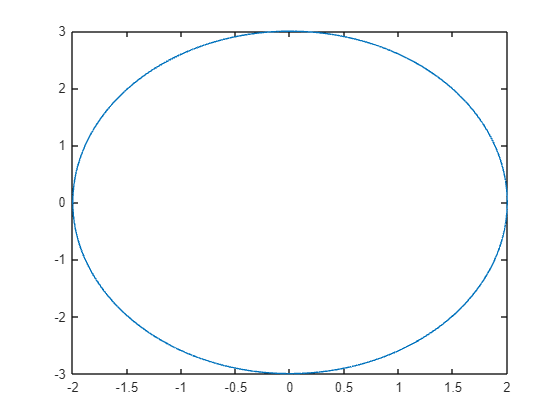

t=linspace(0,2*pi,10000);
x=2*sin(t);
y=3*cos(t);
plot(x,y);

（3）

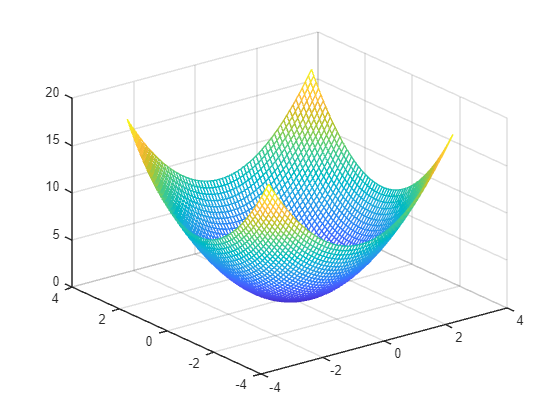

x=-3:0.1:3;
y=x;
[X,Y]=meshgrid(x,y);
Z=X.^2+Y.^2;
mesh(X,Y,Z);

（4）

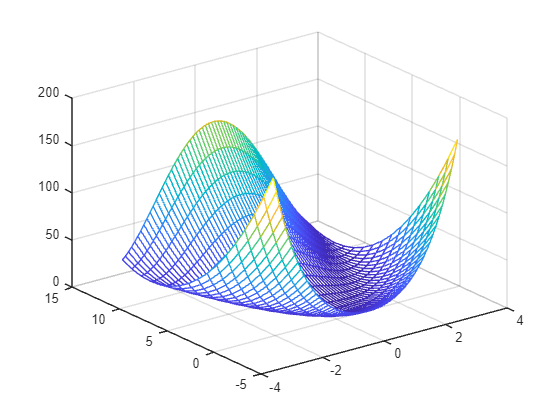

x=-3:0.1:3;
y=-3:13;
[X,Y]=meshgrid(x,y);
Z=X.^4+3.*X.^2+Y.^2-2*X-2*Y-2*(X.^2).*Y+6;
mesh(X,Y,Z);

（5）

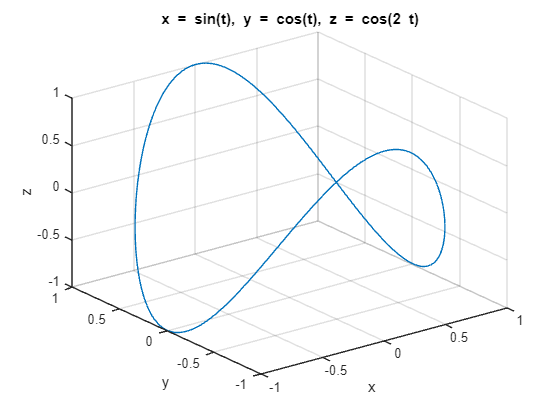

t=0:2*pi;
x='sin(t)';
y='cos(t)';
z='cos(2*t)';
ezplot3(x,y,z)

（6）

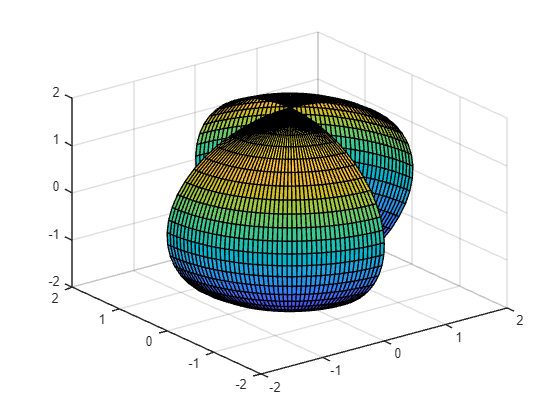

a=linspace(0,2*pi,50);b=linspace(0,pi/2,50);
[a,b]=meshgrid(a,b);
x=2*sin(a).*cos(b);y=2*sin(a).*sin(b);z=2*cos(a);
surf(x,y,z)

 (7)

x=linspace(0,pi,50);y1=sin(x);
plot(x,y1);
hold on;
y2=sin(x).*sin(10*x);
plot(x,y2);
y3=-sin(x);
plot(x,y3);
hold off;

P142

2. 

syms x;
f=x^4-5*x^3+5*x^2+5*x-6;
factor(f)

$$ans = \left(\begin{array}{cccc} x-1 & x-2 & x-3 & x+1 \end{array}\right)$$

3. 

syms a;
A=[1 2; 2 a];
inv(A),eig(A)

$$ans = \left(\begin{array}{cc} \frac{a}{a-4} & -\frac{2}{a-4}\\ -\frac{2}{a-4} & \frac{1}{a-4} \end{array}\right)$$

$$ans = \left(\begin{array}{c} \frac{a}{2}-\frac{\sqrt{a^{2}-2\,a+17}}{2}+\frac{1}{2}\\ \frac{a}{2}+\frac{\sqrt{a^{2}-2\,a+17}}{2}+\frac{1}{2} \end{array}\right)$$

4.(1)

syms x;
limit((3^x+9^x)^(1/x),x,Inf)

$$ans = 9$$

(2)

%f=log10(2*x+exp(-y))/sqrt(x^3+y^2);
%limit(limit(f,y,0,'right'),x,0,'right')

 ans = Inf

5.(1)

syms k n;
symsum(k.^2,1,n)

$$ans = \frac{n\,\left(2\,n+1\right)\,\left(n+1\right)}{6}$$

(2)

syms k;
symsum(1/(k.^2),1,Inf)

$$ans = \frac{\pi^{2}}{6}$$

(3)

syms n x;
s=symsum(1/(2*n+1)/(2*x+1)^(2*n+1),n,0,inf);
s=simplify(s)

$$s = \left\{ \begin{array}{cl} \mathrm{atanh}\left(\frac{1}{2\,x+1}\right) & \text{ if }1<\left|2\,x+1\right| \end{array}\right.$$

6.

syms x y z;
a=diff(sin((x^2)*y*z),x,2)

$$a = 2\,y\,z\,\cos\left(x^{2}\,y\,z\right)-4\,x^{2}\,y^{2}\,z^{2}\,\sin\left(x^{2}\,y\,z\right)$$

a=diff(a,y)

$$a = 2\,z\,\cos\left(x^{2}\,y\,z\right)-10\,x^{2}\,y\,z^{2}\,\sin\left(x^{2}\,y\,z\right)-4\,x^{4}\,y^{2}\,z^{3}\,\cos\left(x^{2}\,y\,z\right)$$

a=subs(a,x,1)

$$a = 2\,z\,\cos\left(y\,z\right)-10\,y\,z^{2}\,\sin\left(y\,z\right)-4\,y^{2}\,z^{3}\,\cos\left(y\,z\right)$$

a=subs(a,y,1)

$$a = 2\,z\,\cos\left(z\right)-10\,z^{2}\,\sin\left(z\right)-4\,z^{3}\,\cos\left(z\right)$$

a=subs(a,z,3)

$$a = -102\,\cos\left(3\right)-90\,\sin\left(3\right)$$

7.

syms x;
f=exp(x);
taylor(f,x,0,'order',8)

$$ans = \frac{x^{7}}{5040}+\frac{x^{6}}{720}+\frac{x^{5}}{120}+\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

f=log(1+x);
taylor(f,x,0,'order',8)

$$ans = \frac{x^{7}}{7}-\frac{x^{6}}{6}+\frac{x^{5}}{5}-\frac{x^{4}}{4}+\frac{x^{3}}{3}-\frac{x^{2}}{2}+x$$

f=sin(x);
taylor(f,x,0,'order',8)

$$ans = -\frac{x^{7}}{5040}+\frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

f=log(x+sqrt(1+x^2));
taylor(f,x,0,'order',8)

$$ans = -\frac{5\,x^{7}}{112}+\frac{3\,x^{5}}{40}-\frac{x^{3}}{6}+x$$

9.

% 7.1
syms y;
f2 = exp(2*y)/(exp(y)+2);
intf(f2,y);

$$fi = {\mathrm{e}}^{y}-2\,\log\left({\mathrm{e}}^{y}+2\right)$$

% 7.2
syms x a;
f3 = x^2/sqrt(a^2-x^2);
intf(f3,x);

$$fi = \frac{a^{2}\,\mathrm{atan}\left(\frac{x}{\sqrt{a^{2}-x^{2}}}\right)}{2}-\frac{x\,\sqrt{a^{2}-x^{2}}}{2}$$

经验证，运算结果正确。

% 7.3
syms x;
syms a b;
assume(a ~= b);
f5 = 1/x/(sqrt(log(x)+a)+sqrt(log(x)+b));
intf(f5,x);

$$fi = \sqrt{a+\log\left(x\right)}\,\left(\frac{2\,a}{3\,a-3\,b}+\frac{2\,\log\left(x\right)}{3\,a-3\,b}\right)-\sqrt{b+\log\left(x\right)}\,\left(\frac{2\,b}{3\,a-3\,b}+\frac{2\,\log\left(x\right)}{3\,a-3\,b}\right)$$

10.

syms x y;
f=(x-y)^3*sin(x+2*y);
Ix=simplify(int(f,y,-x,x))

$$Ix = 4\,x^{3}\,\cos\left(x\right)-3\,x^{2}\,\sin\left(x\right)+\frac{3\,{\cos\left(x\right)}^{2}\,\sin\left(x\right)}{2}-\frac{3\,x\,\cos\left(x\right)}{2}$$

-----------------------YHKCOPYRIGHT--------------------------